lab11

tabA = { [-1,0;0,-2]
    [0,1;-3,2]
    [0,1;-1,0]
    [0,0;0,-1]
    [0,2;0,-1]
    [0.5,0;0,-0.5]
    [0,0.1;0.2,0]
    [0,0;0,1]}

tabA = 8×1 cell array
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}


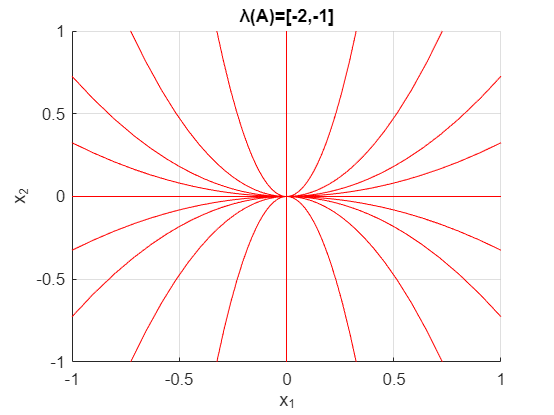

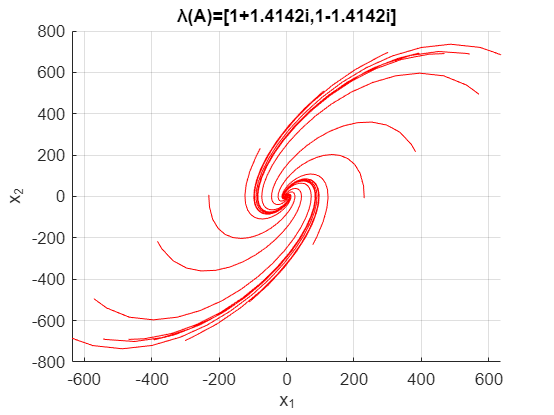

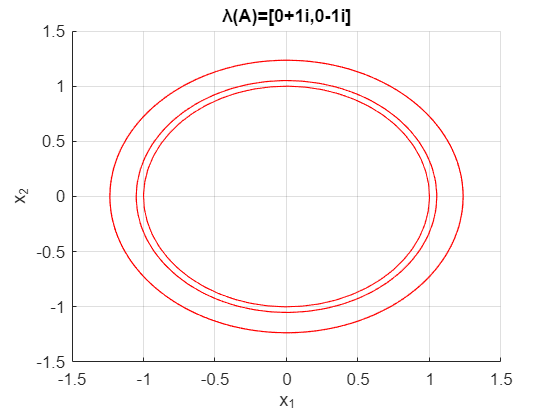

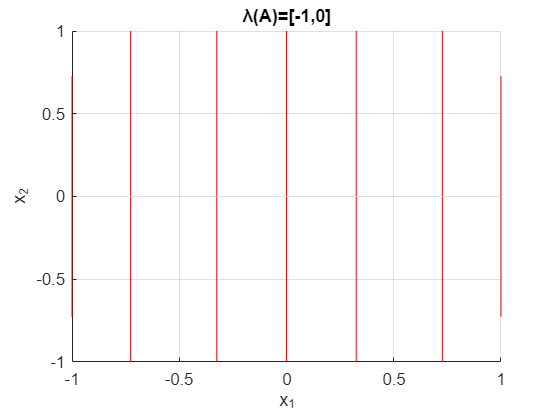

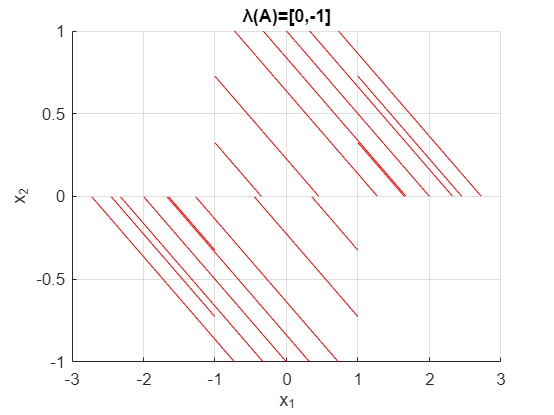

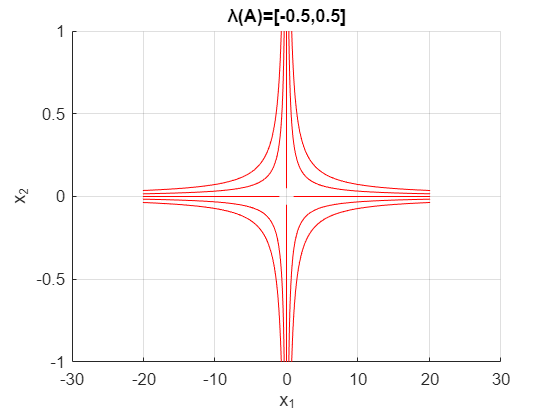

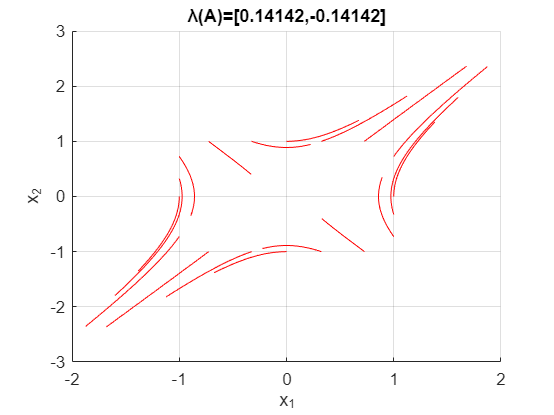

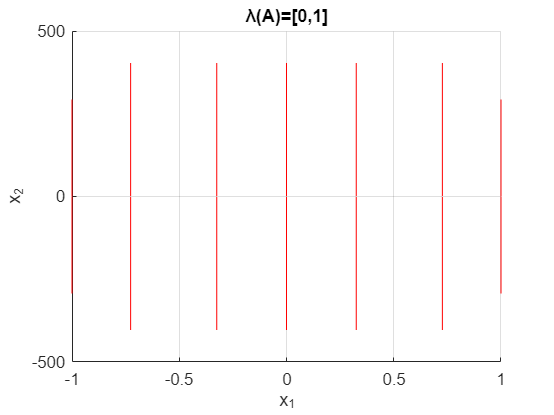



for i = 1:8
    A = cell2mat(tabA(i));
    T = 6;
    [w J]=eig(A);
    figure()
    hold on
    grid on

    a = 0:(pi/10):(2*pi);
    X1 =[cos(a);sin(a)];
        X2 = X1./[max(abs(X1))];
    max(abs(X1));
    M = size(X2,2);

    for m=1:M
        x0 = X2(:,m);
        out = sim('untitled',T);
        plot(x(:,1),x(:,2),'r-');
        title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']']);
        xlabel('x_1'); 
        ylabel('x_2');
    % xlim([-1 -1])
    % ylim([1 1])
    end

    
end